# **Week L0: Single-Carrier with Alamouti Coding**

This script implements a simplified optic fibre communications system using Alamouti coding

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using QPSK

- A pulse shaper which creates an electrical signal using the generated symbols

- An IQ modulator which modulates the output of a laser according to an electrical signal

### Alamouti Coding

clear all; clearvars;

% Parameters
NSymb = 400000; % No. of symbols 
SpS = 1; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevelsQPSK = [asin(-1/sqrt(2)), asin(1/sqrt(2))]'; % Discrete voltages for QAM
voltageLevelsQAM = [asin(-3/sqrt(10)), asin(-1/sqrt(10)), asin(1/sqrt(10)), asin(3/sqrt(10))]';
DCOffset = 0; % DC offset of modulated current in V

% --------------------------------------------------------------------------------------

% FOR QPSK:
% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, 1); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4); % Maps source bit vector to symbol vector
codedSymbolsQPSK = AlamoutiCoding(sourceSymbolsQPSK); % Encodes symbols using Alamouti coding

% Modulating voltage with generated symbols
vI_QPSK = ones(size(codedSymbolsQPSK)); vQ_QPSK = zeros(size(codedSymbolsQPSK));

vI_QPSK(real(codedSymbolsQPSK)>0) = voltageLevelsQPSK(2); % Maps 1 -> asin(1/sqrt(2))
vI_QPSK(real(codedSymbolsQPSK)<0) = voltageLevelsQPSK(1); % Maps -1 -> asin(-1/sqrt(2))
vQ_QPSK(imag(codedSymbolsQPSK)>0) = voltageLevelsQPSK(2); % Maps 1 -> asin(1/sqrt(2))
vQ_QPSK(imag(codedSymbolsQPSK)<0) = voltageLevelsQPSK(1); % Maps -1 -> asin(-1/sqrt(2))

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
% stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1), "o-");
% title("Modulated Voltage for QPSK")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

### Pulse Shaping

% RRC filter parameters
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");

% stem(filterResponse_t, filterResponse, '-o');
% title('Impulse Response of RRC Filter');
% xlabel('Time / s');
% ylabel('Normalised Amplitude');
% grid on

% ---------------------------------------------------------------------------

% FOR QPSK:
% Using RRC filter to shape vI and vQ

vI_QPSK_shaped = upfirdn(vI_QPSK, filterResponse, SpS, 1); vQ_QPSK_shaped = upfirdn(vQ_QPSK, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QPSK = fftshift(fft(vI_QPSK_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QPSK_shaped = fftshift(fft(vI_QPSK_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

% stem(freqArr, abs(fft_vI_QPSK), "|");
% hold on
% stem(freqArr_shaped, abs(fft_vI_QPSK_shaped), "|");
% title("FFT of In-Phase Voltage - QPSK");
% xlabel("f / Hz");
% ylabel("|fft(vI)|");
% legend("Before Shaping", "After Shaping");
% hold off
% grid on

% Visualising pulse-shaped voltages
% stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_upsampled(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_shaped(1:10*SpS + filterSpan,1), "o-");
% title("Shaped In-Phase Voltage - QPSK");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After shaping");
% grid on
% hold off

bandwidth = 0.5*(1+rollOff)/T

bandwidth = 3.7500e+10

### IQ Modulation

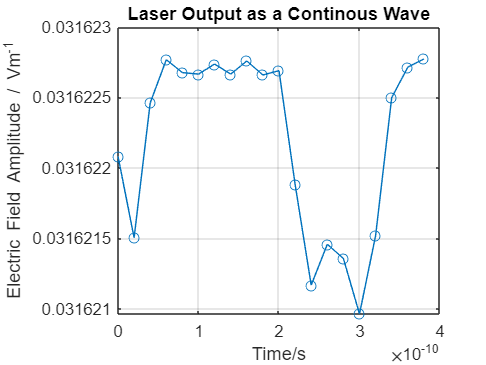

% Initialising laser parameters
lineWidth = 1e5;
laserPw_dBm = 0;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a contniuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % Laser output to be used with shaped signals

% Visualising output from laser
plot(t(1:20), real(laserE(1:20)), "o-");
title("Laser Output as a Continous Wave");
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}");
grid on


% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

% Unshaped Signals
modOpticSigQPSK = IQModulatorModified(vI_QPSK_upsampled, vQ_QPSK_upsampled, laserE, Vpi);

% Visualising modulated optical signals
% stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1)), "o-");
% title("Modulated Optical Signals")
% xlabel("Time/s")
% ylabel("Electric Field Amplitude / Vm^{-1}")
% grid on

## Optical Channel

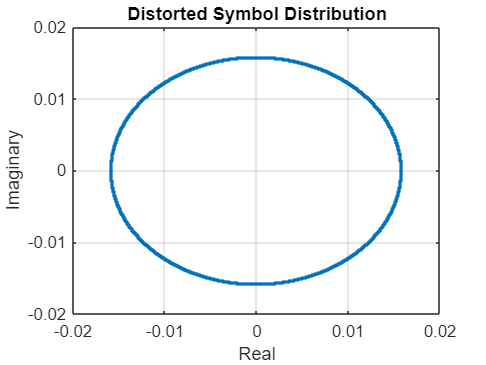

% Inserting CD
D = 17; % Group velocity dispersion in ps/nm/km
CLambda = 1550e-9; % Central wavelength of optical carrier in m
linkLength = 50e3; % Fibre link length in m

% for i=1:2
%     modOpticSigQPSK_CD(:,i) = CDInsertion(modOpticSigQPSK(:,i), SpS, Rs, D, CLambda, linkLength, 1);
% end

% Inserting rotations
thetaArr = 0; 
for i=1:size(thetaArr,2)
    modOpticSigQPSK_rot(:,:,i) = PolRotate(modOpticSigQPSK, 0, thetaArr(i));
end

% Visualising symbol distribution
plot(modOpticSigQPSK_rot(:,1,1), ".", lineWidth=3);
title("Distorted Symbol Distribution");
xlabel("Real")
ylabel("Imaginary")
grid on

### Optical Front-End

% Generating Local optical signal for coherent detection
% carr_freq = 3e8/(1550e-9); % Carrier frequency in ms-1
% freq_offset = 0; % LO signal frequency offset

Elo = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 1); % LO signal with non-zero linewidth for unshaped signals
Elo_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 1); % LO signal with non-zero linewidth for shaped signals
% Elo_shifted = LOFrequencyShift(Elo, freq_offset, T); % Frequency-shifted LO signal for unshaped information signal
% Elo_shaped_shifted = LOFrequencyShift(Elo_shaped, freq_offset, T); % Frequency-shifted LO signal for shaped information signal

% Visualising locally generated optical signal
% plot(t(1:20), real(Elo(1:20,1)), "-o");
% hold on
% plot(t(1:20), real(Elo_shifted(1:20,1)), "-o");
% title("Locally Generated Optical Signal");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude/ Vm^{-1}")
% legend("Ideal", "Frequency-Shifted")
% hold off
% grid on

% Visualising FFTs of original and frequency shifted LO laser signal
% fft_Elo = fftshift(fft(Elo(:,1))); % FFT of original LO signal
% fft_Elo_shifted = fftshift(fft(real(Elo_shifted(:,1)))); % FFT of frequency-shifted LO signal
% freqArr_Elo = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

% stem(freqArr_Elo, abs(fft_Elo), "|");
% hold on
% stem(freqArr_Elo, abs(fft_Elo_shifted), "|");
% title("FFT of LO Signals");
% xlabel("f / Hz");
% ylabel("|fft(Elo)|");
% legend("Matched signal", "Frequency-shifted signal");
% hold off
% grid on


% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors
OpticFEOutQPSK = OpticalFrontEnd(modOpticSigQPSK, [Elo Elo], eta_ph, 2); % Unshaped
% OpticFEOutQPSK_CD = OpticalFrontEnd(modOpticSigQPSK_CD, [Elo Elo], eta_ph, 2); % Unshaped + CD
% OpticFEOutQPSK_rot = OpticalFrontEnd(modOpticSigQPSK_rot, [Elo Elo], eta_ph, 2); % Unshaped + rotation

% Unshaped + rotation
OpticFEOutQPSK_rot = zeros(size(modOpticSigQPSK_rot,1), 2*size(modOpticSigQPSK_rot,2),size(modOpticSigQPSK_rot,3));
for i=1:size(modOpticSigQPSK_rot,3)
    OpticFEOutQPSK_rot(:,:,i) = OpticalFrontEnd(modOpticSigQPSK_rot(:,:,i), [Elo Elo], eta_ph, 2);
end

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components of the two polarizations
% QPSK
OpticFEOutQPSK_I = TIA_Gain*OpticFEOutQPSK(:,1:2:end); OpticFEOutQPSK_Q = TIA_Gain*OpticFEOutQPSK(:,2:2:end); % Unshaped 
% OpticFEOutQPSK_CD_I = TIA_Gain*OpticFEOutQPSK_CD(:,1:2:end); OpticFEOutQPSK_CD_Q = TIA_Gain*OpticFEOutQPSK_CD(:,2:2:end); % Unshaped + CD
OpticFEOutQPSK_rot_I = TIA_Gain*OpticFEOutQPSK_rot(:,1:2:end,:); OpticFEOutQPSK_rot_Q = TIA_Gain*OpticFEOutQPSK_rot(:,2:2:end,:); % Unshaped + rotated

% OpticFEOutQPSK_shaped_I = TIA_Gain*OpticFEOutQPSK_shaped(:,1:2:end); OpticFEOutQPSK_shaped_Q = TIA_Gain*OpticFEOutQPSK_shaped(:,2:2:end); % Shaped 

## DSP

### Scaling and Downsampling

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
% scaleFactor=1;
scaleFactor = TIA_Gain*eta_ph*laserEMag*laserEMag/2;

% Cancelling the scaling factor and downsampling:

% % QPSK
voltageQPSK_I = OpticFEOutQPSK_I(1:SpS:end,:)/scaleFactor; voltageQPSK_Q = OpticFEOutQPSK_Q(1:SpS:end,:)/scaleFactor; % Unshaped 
% voltageQPSK_CD_I = OpticFEOutQPSK_CD_I(1:SpS:end,:)/scaleFactor; voltageQPSK_CD_Q = OpticFEOutQPSK_CD_Q(1:SpS:end,:)/scaleFactor; % Unshaped + CD
voltageQPSK_rot_I = OpticFEOutQPSK_rot_I(1:SpS:end,:,:)/scaleFactor; voltageQPSK_rot_Q = OpticFEOutQPSK_rot_Q(1:SpS:end,:,:)/scaleFactor; % Unshaped + CD

% voltageQPSK_shaped_I = upfirdn(OpticFEOutQPSK_shaped_I/scaleFactor, filterResponse, 1, SpS); voltageQPSK_shaped_I = voltageQPSK_shaped_I(filterSpan + 1:end - filterSpan,:); % Shaped 
% voltageQPSK_shaped_Q = upfirdn(OpticFEOutQPSK_shaped_Q/scaleFactor, filterResponse, 1, SpS); voltageQPSK_shaped_Q = voltageQPSK_shaped_Q(filterSpan + 1:end - filterSpan,:); % Shaped 

### Adaptive Equalziation

% Without channel distortion
NTaps = 25; NRemove = 380000; N1 = 100000; Mu_T = 1e-4; Mu_DD = 1e-4; Mu_p = 1e-4;

% trainSymbsQPSK = codedSymbolsQPSK; % trainSymbsQPSK(2:2:end) = conj(trainSymbsQPSK(2:2:end));
trainSymbsQPSK = sourceSymbolsQPSK;

% Unshaped
% [equalizedSymbsQPSK, pQPSK, w11QPSK, w12QPSK, w21QPSK, w22QPSK, errQPSK] = AdapEqualizerAlamouti(voltageQPSK_I(:,1)+1i*voltageQPSK_Q(:,1), trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Unshaped
% [equalizedSymbsQPSK_CD, pQPSK_CD, w11QPSK_CD, w12QPSK_CD, w21QPSK_CD, w22QPSK_CD, errQPSK_CD] = AdapEqualizerAlamouti(voltageQPSK_CD_I(:,1)+1i*voltageQPSK_CD_Q(:,1), trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Unshaped + CD

equalizedSymbsQPSK_rot = zeros(NSymb,size(thetaArr,2));
for i=1:size(thetaArr,2)
    [equalizedSymbsQPSK_rot(:,i),pQPSK_rot,w11QPSK_rot,w12QPSK_rot,w21QPSK_rot,w22QPSK_rot,errQPSK_rot] = AdapEqualizerAlamouti(voltageQPSK_rot_I(:,1,i)+1i*voltageQPSK_rot_Q(:,1,i), trainSymbsQPSK, SpS, NTaps, Mu_T, Mu_DD, Mu_p, N1, 'QPSK'); % Unshaped + rotation
end

% Shaped
% [equalizedSymbsQPSK_shaped, pQPSK_shaped, w11QPSK_shaped, w12QPSK_shaped, w21QPSK_shaped, w22QPSK_shaped] = AdapEqualizerAlamouti(voltageQPSK_shaped_I(:,1)+1i*voltageQPSK_shaped_Q(:,1), sourceSymbolsQPSK, SpS, NTaps, 0.0001, 0.0001, 100000, 'QPSK');

% Visualising evolution of filter coefficients
% plot([1:size(pQPSK)], w11QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{11}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], w12QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{12}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], w21QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{21}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], w22QPSK', '-');
% title("QPSK Filter Coefficient Variation - w_{22}")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK)], pQPSK, '-');
% title("QPSK p variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(errQPSK(:,1))], abs(errQPSK(:,1)), '-');
% title("QPSK Odd Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(errQPSK(:,2))], abs(errQPSK(:,2)), '-');
% title("QPSK Even Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot(voltageQPSK_I(:,1)+1i*voltageQPSK_Q(:,1), '+');
% hold on
% title("Symbol Distribution")
% plot(equalizedSymbsQPSK(1:NRemove), '.');
% plot(equalizedSymbsQPSK(NRemove+1:end), '.');
% plot(sourceSymbolsQPSK, '+', LineWidth=2);
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before Equalization", "Training", "DD")
% grid on
% hold off


% ----------------------------------------------------------------------------
% With CD added

% Visualising evolution of filter coefficients
% plot([1:size(pQPSK_CD)], w11QPSK_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{11} with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_CD)], w12QPSK_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{12} with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_CD)], w21QPSK_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{21} with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_CD)], w22QPSK_CD', '-');
% title("QPSK Filter Coefficient Variation - w_{22} with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(pQPSK_CD)], pQPSK_CD, '-');
% title("QPSK p variation with CD")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(errQPSK_CD(:,1))], abs(errQPSK_CD(:,1)), '-');
% title("QPSK Odd Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot([1:size(errQPSK_CD(:,2))], abs(errQPSK_CD(:,2)), '-');
% title("QPSK Even Symbol Error Variation")
% xlabel("Iteration")
% ylabel("Value")
% grid on
% 
% plot(voltageQPSK_CD_I(:,1)+1i*voltageQPSK_CD_Q(:,1), '.');
% hold on
% title("Symbol Distribution")
% plot(equalizedSymbsQPSK_CD(1:NRemove), '.');
% plot(equalizedSymbsQPSK_CD(NRemove+1:end), '.');
% plot(sourceSymbolsQPSK, '+', LineWidth=2);
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before Equalization", "Training", "DD")
% grid on
% hold off


% ----------------------------------------------------------------------------
% With rotation

% Visualising evolution of filter coefficients
plot([1:size(pQPSK_rot)], w11QPSK_rot', '-');

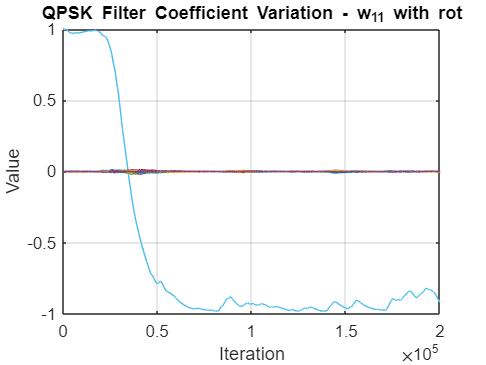

title("QPSK Filter Coefficient Variation - w_{11} with rot")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK_rot)], w12QPSK_rot', '-');

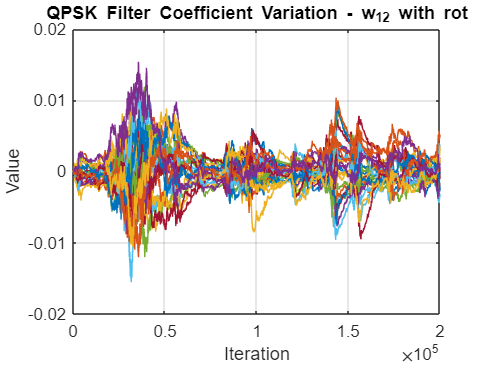

title("QPSK Filter Coefficient Variation - w_{12} with rot")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK_rot)], w21QPSK_rot', '-');

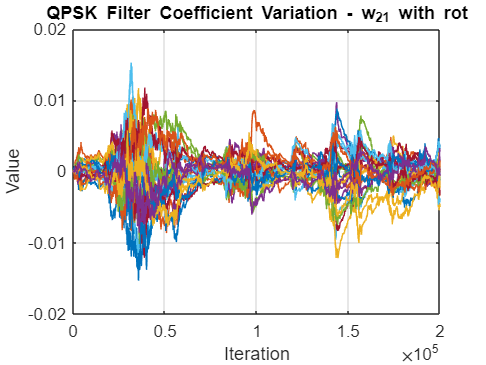

title("QPSK Filter Coefficient Variation - w_{21} with rot")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK_rot)], w22QPSK_rot', '-');

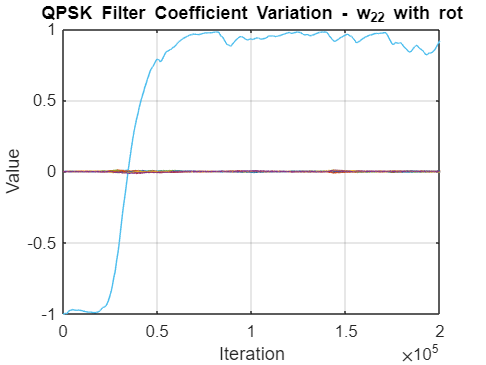

title("QPSK Filter Coefficient Variation - w_{22} with rot")
xlabel("Iteration")
ylabel("Value")
grid on


plot([1:size(pQPSK_rot)], pQPSK_rot, '-');

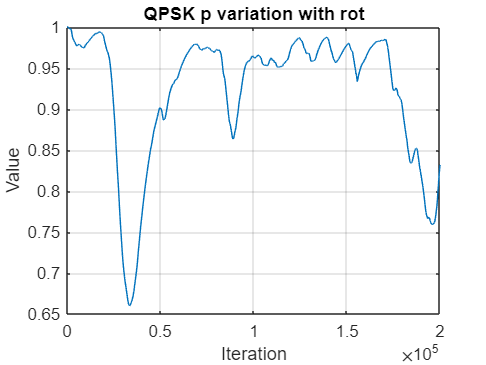

title("QPSK p variation with rot")
xlabel("Iteration")
ylabel("Value")
grid on

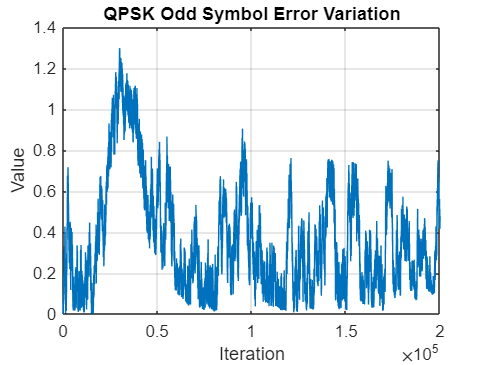


plot([1:size(errQPSK_rot(:,1))], abs(errQPSK_rot(:,1)), '-');
title("QPSK Odd Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

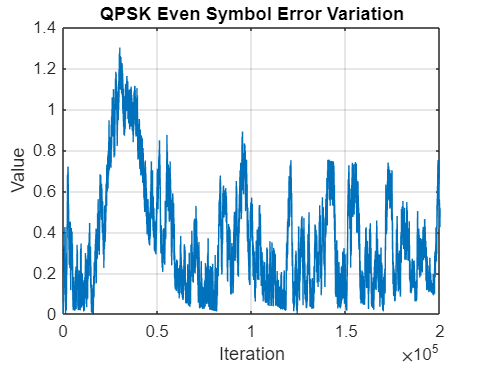


plot([1:size(errQPSK_rot(:,2))], abs(errQPSK_rot(:,2)), '-');
title("QPSK Even Symbol Error Variation")
xlabel("Iteration")
ylabel("Value")
grid on

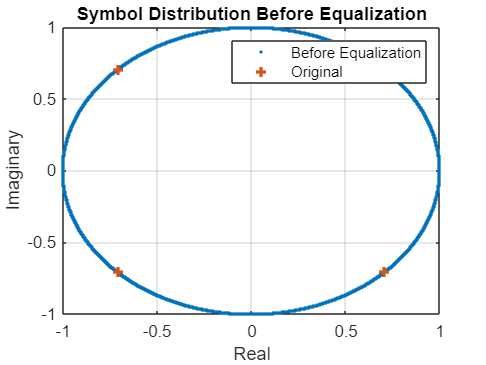


plot(voltageQPSK_rot_I(:,1,end)+1i*voltageQPSK_rot_Q(:,1,end), '.', LineWidth=2);
hold on
plot(sourceSymbolsQPSK, '+', LineWidth=2);
title("Symbol Distribution Before Equalization")
xlabel("Real")
ylabel("Imaginary")
legend("Before Equalization", "Original")
grid on
hold off

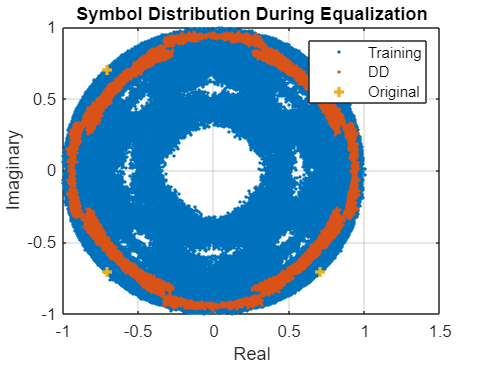


plot(equalizedSymbsQPSK_rot(1:NRemove,end), '.');
hold on
plot(equalizedSymbsQPSK_rot(NRemove+1:end,end), '.');
plot(sourceSymbolsQPSK, '+', LineWidth=2);
title("Symbol Distribution During Equalization")
xlabel("Real")
ylabel("Imaginary")
legend("Training", "DD","Original")
grid on
hold off

## Receiver

### Decoding and Decision

% Without MIMO equalization:
% Unshaped
% testSymbolsQPSK = voltageQPSK_I(:,1) + 1i*voltageQPSK_Q(:,1);
% testSymbolsQPSK(2:2:end,1) = -1*conj(testSymbolsQPSK(2:2:end,1));
% testIntsQPSK = pskdemod(testSymbolsQPSK, 4, pi/4);
% testBitsQPSK = int2bit(testIntsQPSK, 2);
% biterr(testBitsQPSK, sourceBitsQPSK)

% Shaped
% testSymbolsQPSK_shaped = voltageQPSK_shaped_I(:,1) + 1i*voltageQPSK_shaped_Q(:,1);
% testSymbolsQPSK_shaped(2:2:end,1) = -1*conj(testSymbolsQPSK_shaped(2:2:end,1));
% testIntsQPSK_shaped = pskdemod(testSymbolsQPSK_shaped, 4, pi/4);
% testBitsQPSK_shaped = int2bit(testIntsQPSK_shaped, 2);
% biterr(testBitsQPSK_shaped, sourceBitsQPSK)

% -------------------------------------------------------------------------------

% With MIMO Eqaulization
% Unshaped
% After Equalization
% equalizedIntsQPSK_train = pskdemod(equalizedSymbsQPSK(1:N1*2,:), 4, pi/4);
% equalizedBitsQPSK_train = int2bit(equalizedIntsQPSK_train, 2);
% [~, BERQPSK_train] = biterr(equalizedBitsQPSK_train, sourceBitsQPSK(1:N1*4))
% 
% equalizedIntsQPSK_dd = pskdemod(equalizedSymbsQPSK(N1*2+1:end,:), 4, pi/4);
% equalizedBitsQPSK_dd = int2bit(equalizedIntsQPSK_dd, 2);
% [~, BERQPSK_dd] = biterr(equalizedBitsQPSK_dd, sourceBitsQPSK(N1*4+1:end))
% 
% equalizedIntsQPSK = pskdemod(equalizedSymbsQPSK(NRemove+1:end,:), 4, pi/4);
% equalizedBitsQPSK = int2bit(equalizedIntsQPSK, 2);
% [~, BERQPSK] = biterr(equalizedBitsQPSK, sourceBitsQPSK(NRemove*2+1:end))

% ----------------------

% Unshaped + CD
% Before equalization
% distortedSymbsQPSK = voltageQPSK_CD_I(:,1)+1i*voltageQPSK_CD_Q(:,1);
% distortedSymbsQPSK(2:2:end,1) = -1*conj(distortedSymbsQPSK(2:2:end,1));
% IntsQPSK_CD = pskdemod(distortedSymbsQPSK, 4, pi/4);
% BitsQPSK_CD = int2bit(IntsQPSK_CD, 2);
% [~, BERQPSK_CD_before] = biterr(BitsQPSK_CD, sourceBitsQPSK)

% After equalization
% equalizedIntsQPSK_CD_train = pskdemod(equalizedSymbsQPSK_CD(1:N1*2,:), 4, pi/4);
% equalizedBitsQPSK_CD_train = int2bit(equalizedIntsQPSK_CD_train, 2);
% [~, BERQPSK_CD_train] = biterr(equalizedBitsQPSK_CD_train, sourceBitsQPSK(1:N1*4))
% 
% equalizedIntsQPSK_CD_dd = pskdemod(equalizedSymbsQPSK_CD(N1*2+1:end,:), 4, pi/4);
% equalizedBitsQPSK_CD_dd = int2bit(equalizedIntsQPSK_CD_dd, 2);
% [~, BERQPSK_CD_dd] = biterr(equalizedBitsQPSK_CD_dd, sourceBitsQPSK(N1*4+1:end))
% 
% equalizedIntsQPSK_CD = pskdemod(equalizedSymbsQPSK_CD(NRemove+1:end,:), 4, pi/4);
% equalizedBitsQPSK_CD = int2bit(equalizedIntsQPSK_CD, 2);
% [~, BERQPSK_CD] = biterr(equalizedBitsQPSK_CD, sourceBitsQPSK(NRemove*2+1:end))


% ----------------------

% Unshaped + rotation
% Before equalization
distortedSymbsQPSK = voltageQPSK_rot_I(:,1)+1i*voltageQPSK_rot_Q(:,1);
distortedSymbsQPSK(2:2:end,1) = -1*conj(distortedSymbsQPSK(2:2:end,1));
IntsQPSK_rot = pskdemod(distortedSymbsQPSK, 4, pi/4);
BitsQPSK_rot = int2bit(IntsQPSK_rot, 2);
[~, BERQPSK_rot_before] = biterr(BitsQPSK_rot, sourceBitsQPSK)

BERQPSK_rot_before = 0.6336


% After equalization
equalizedIntsQPSK_rot_train = pskdemod(equalizedSymbsQPSK_rot(1:N1*2,:), 4, pi/4);
equalizedBitsQPSK_rot_train = int2bit(equalizedIntsQPSK_rot_train, 2);
[~, BERQPSK_rot_train] = biterr(equalizedBitsQPSK_rot_train, sourceBitsQPSK(1:N1*4))

BERQPSK_rot_train = 0.0979


equalizedIntsQPSK_rot_dd = pskdemod(equalizedSymbsQPSK_rot(N1*2+1:end,:), 4, pi/4);
equalizedBitsQPSK_rot_dd = int2bit(equalizedIntsQPSK_rot_dd, 2);
[~, BERQPSK_rot_dd] = biterr(equalizedBitsQPSK_rot_dd, sourceBitsQPSK(N1*4+1:end))

BERQPSK_rot_dd = 0.5127


equalizedIntsQPSK_rot = pskdemod(equalizedSymbsQPSK_rot(NRemove+1:end,:), 4, pi/4);
equalizedBitsQPSK_rot = int2bit(equalizedIntsQPSK_rot, 2);
[~, BERQPSK_rot] = biterr(equalizedBitsQPSK_rot, sourceBitsQPSK(NRemove*2+1:end))

BERQPSK_rot = 0.9991



% ---------------------------------------------------------------------------------------

% Shaped
% equalizedIntsQPSK_shaped = pskdemod(equalizedSymbsQPSK_shaped(NRemove+1:end,:), 4, pi/4);
% equalizedBitsQPSK_shaped = int2bit(equalizedIntsQPSK_shaped, 2);
% biterr(equalizedBitsQPSK_shaped, sourceBitsQPSK(NRemove*2+1:end))
